clear all; clc;

I = 48;
Fs = 16000;
FsI = Fs*I;

%2 stage interpolator
d2 = fdesign.interpolator(I,'nyquist',I,'TW,Ast',1200,58,FsI)

d2 =   interpolator with properties:

          MultirateType: 'Interpolator'
               Response: 'Nyquist'
    InterpolationFactor: 48
          Specification: 'TW,Ast'
            Description: {2×1 cell}
                   Band: 48
    NormalizedFrequency: 0
                     Fs: 768000
                  Fs_in: 16000
                 Fs_out: 768000
        TransitionWidth: 1200
                  Astop: 58


filt2stage = design(d2,'multistage','Nstages',2,'SystemObject',true);

%2 order and cost
filt2stage.order

ans = 2320

length(filt2stage)

ans = 1

filt2stage.cost

ans = struct with fields:
                  NumCoefficients: 170
                        NumStates: 51
    MultiplicationsPerInputSample: 322
          AdditionsPerInputSample: 275



fvtool(filt2stage);

%implement signal into lowpass and Interpolation
load Sa1.mat;

wavedata_48I = filt2stage(wavedata);

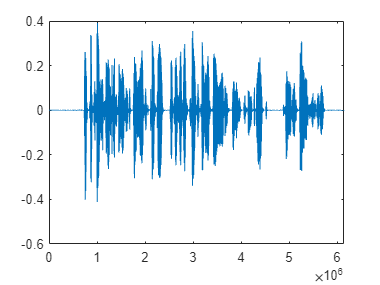

%analyse output
plot(wavedata_48I);

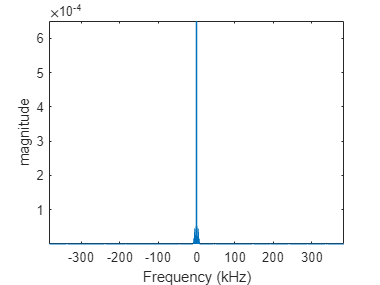

plotfft(wavedata_48I,1/FsI,[-FsI/2000 FsI/2000]);